my_tab = readtable('bh_hello_complete.xlsx', 'Sheet', 'COMP_SPLINE _4dof');

head(my_tab)

ans = 8×7 table
     T          XE           YE          ZE           DXDT           DYDT           DZDT   
    ____    ___________    ______    __________    ___________    ___________    __________

       0              0       1.5             0              0              0             0
    0.01      -4.28e-07       1.5    9.0415e-07    -8.5543e-05    -0.00067555    0.00018077
    0.02    -1.7097e-06       1.5    3.6141e-06    -0.00017074     -0.0013498    0.00036117
    0.03    -3.8417e-06       1.5    8.1263e-06     -0.0002556     -0.0020228     0.0005412
    0.04    -6.8206e-06    1.4999    1.4437e-05    -0.00034011     -0.0026945    0.00072086
    0.05    -1.0643e-05    1.4999    2.2542e-05    -0.00042429     -0.0033649    0.00090016
    0.06 

So create some TIMESERIES objects:

`TIP:  ts = timeseries(datavals,timevals)`

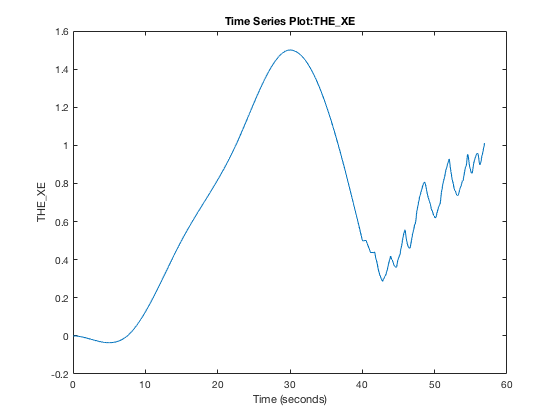

xe_ts = timeseries(my_tab.XE, my_tab.T,'Name','THE_XE');
ye_ts = timeseries(my_tab.YE, my_tab.T,'Name','THE_YE');
ze_ts = timeseries(my_tab.ZE, my_tab.T,'Name','THE_ZE');

figure;
plot(xe_ts)

Or create a STRUCT of Time series objects:

xyz_str_ts.xe = xe_ts;
xyz_str_ts.ye = ye_ts;
xyz_str_ts.ze = ze_ts;

And you'll need a BUS definition for this struct also:

%Simulink.Bus.createObject(xyz_str_ts, 'the_xyz_bus_def_file.m', 'object')
Simulink.Bus.createObject(xyz_str_ts)
MY_XYZ_BUS_DEF = slBus1;

And for the FROM_FILE example we'll save a MAT file:

MY_TS_ARRAY = [xe_ts; ye_ts; ze_ts];
save my_MAT_FILE.mat -v7.3 xyz_str_ts